### Assumptions:

    1. Small angles: $\sin \left(\theta \;\right)=\theta \;$

clear all
k = [100,100,100,100];
c = [0,0,0,0];

syms L1 L2
syms k1 k2 k3 k4
syms c1 c2 c3 c4
syms m1 m2 m3 I1

syms x1 x1_dot x1_ddot
syms x2 x2_dot x2_ddot
syms x3 x3_dot x3_ddot

syms theta theta_dot theta_ddot




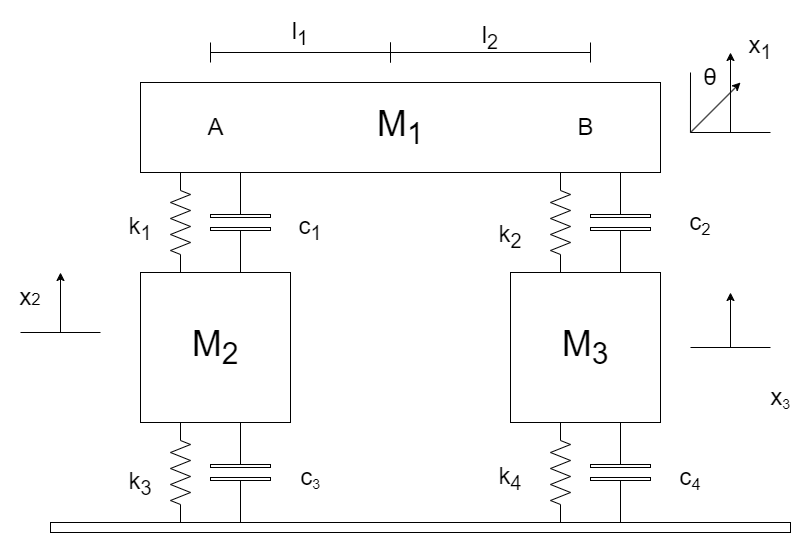

F_A = k1*(x1-x2-L1*theta)+c1*(x1_dot -x2_dot-L1*theta_dot)

$$F\_A = -c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)-k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)$$

F_B = k2*(x1-x3-L2*theta)+c2*(x1_dot -x3_dot-L2*theta_dot)

$$F\_B = -c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)-k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)$$


F2 =k3*x2 + c3*x2_dot

$$F2 = c_{3}\,x_{\dot{2}}+k_{3}\,x_{2}$$

F3 = k4*x3 + c4*x3_dot

$$F3 = c_{4}\,x_{\dot{3}}+k_{4}\,x_{3}$$

Create Equations based on these forces & newtons 2nd law

EQ_2 = m2*x2_ddot == F_A - F2

$$EQ\_2 = m_{2}\,x_{\ddot{2}}=-c_{3}\,x_{\dot{2}}-k_{3}\,x_{2}-c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)-k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)$$

EQ_3 = m3*x3_ddot == F_B - F3

$$EQ\_3 = m_{3}\,x_{\ddot{3}}=-c_{4}\,x_{\dot{3}}-k_{4}\,x_{3}-c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)-k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)$$



EQ_1 = m1 * x1_ddot - (F_A + F_B)

$$EQ\_1 = m_{1}\,x_{\ddot{1}}+c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)+c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)+k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)+k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)$$

Create the equation for the roll of the rig

EQ_1_Roll = I1 * theta_ddot == F_A*L1-F_B*L2

$$EQ\_1\_Roll = I_{1}\,\ddot{\theta }=L_{2}\,\left(c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)+k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)\right)-L_{1}\,\left(c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)+k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)\right)$$





System_EQ = [EQ_1;
             EQ_1_Roll;
             EQ_2;
             EQ_3]

$$System\_EQ = \begin{array}{l} \left(\begin{array}{c} m_{1}\,x_{\ddot{1}}+\sigma_{2}+\sigma_{1}+\sigma_{4}+\sigma_{3}\\ I_{1}\,\ddot{\theta }=L_{2}\,\left(\sigma_{1}+\sigma_{3}\right)-L_{1}\,\left(\sigma_{2}+\sigma_{4}\right)\\ m_{2}\,x_{\ddot{2}}=-c_{3}\,x_{\dot{2}}-k_{3}\,x_{2}-\sigma_{2}-\sigma_{4}\\ m_{3}\,x_{\ddot{3}}=-c_{4}\,x_{\dot{3}}-k_{4}\,x_{3}-\sigma_{1}-\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{2}\,\left(x_{\dot{3}}-x_{\dot{1}}+L_{2}\,\dot{\theta }\right)\\ \sigma_{2}=c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)\\ \sigma_{3}=k_{2}\,\left(x_{3}-x_{1}+L_{2}\,\theta \right)\\ \sigma_{4}=k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right) \end{array}$$

matrix_format = [x1_ddot, theta_ddot,x2_ddot,x3_ddot,...
                 x1_dot, theta_dot, x2_dot, x3_dot,...
                 x1,     theta,      x2,     x3;]

$$matrix\_format = \left(\begin{array}{cccccccccccc} x_{\ddot{1}} & \ddot{\theta } & x_{\ddot{2}} & x_{\ddot{3}} & x_{\dot{1}} & \dot{\theta } & x_{\dot{2}} & x_{\dot{3}} & x_{1} & \theta & x_{2} & x_{3} \end{array}\right)$$


[A,F_Mat] = equationsToMatrix(System_EQ,matrix_format)

$$A = \left(\begin{array}{cccccccccccc} m_{1} & 0 & 0 & 0 & -c_{1}-c_{2} & L_{1}\,c_{1}+L_{2}\,c_{2} & c_{1} & c_{2} & -k_{1}-k_{2} & L_{1}\,k_{1}+L_{2}\,k_{2} & k_{1} & k_{2}\\ 0 & I_{1} & 0 & 0 & L_{2}\,c_{2}-L_{1}\,c_{1} & {L_{1}}^{2}\,c_{1}-{L_{2}}^{2}\,c_{2} & L_{1}\,c_{1} & -L_{2}\,c_{2} & L_{2}\,k_{2}-L_{1}\,k_{1} & {L_{1}}^{2}\,k_{1}-{L_{2}}^{2}\,k_{2} & L_{1}\,k_{1} & -L_{2}\,k_{2}\\ 0 & 0 & m_{2} & 0 & -c_{1} & L_{1}\,c_{1} & c_{1}+c_{3} & 0 & -k_{1} & L_{1}\,k_{1} & k_{1}+k_{3} & 0\\ 0 & 0 & 0 & m_{3} & -c_{2} & L_{2}\,c_{2} & 0 & c_{2}+c_{4} & -k_{2} & L_{2}\,k_{2} & 0 & k_{2}+k_{4} \end{array}\right)$$

$$F\_Mat = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

M_Mat = A(:,1:4)

$$M\_Mat = \left(\begin{array}{cccc} m_{1} & 0 & 0 & 0\\ 0 & I_{1} & 0 & 0\\ 0 & 0 & m_{2} & 0\\ 0 & 0 & 0 & m_{3} \end{array}\right)$$

C_Mat = A(:,5:8)

$$C\_Mat = \left(\begin{array}{cccc} -c_{1}-c_{2} & L_{1}\,c_{1}+L_{2}\,c_{2} & c_{1} & c_{2}\\ L_{2}\,c_{2}-L_{1}\,c_{1} & {L_{1}}^{2}\,c_{1}-{L_{2}}^{2}\,c_{2} & L_{1}\,c_{1} & -L_{2}\,c_{2}\\ -c_{1} & L_{1}\,c_{1} & c_{1}+c_{3} & 0\\ -c_{2} & L_{2}\,c_{2} & 0 & c_{2}+c_{4} \end{array}\right)$$

K_Mat = A(:,9:12)

$$K\_Mat = \left(\begin{array}{cccc} -k_{1}-k_{2} & L_{1}\,k_{1}+L_{2}\,k_{2} & k_{1} & k_{2}\\ L_{2}\,k_{2}-L_{1}\,k_{1} & {L_{1}}^{2}\,k_{1}-{L_{2}}^{2}\,k_{2} & L_{1}\,k_{1} & -L_{2}\,k_{2}\\ -k_{1} & L_{1}\,k_{1} & k_{1}+k_{3} & 0\\ -k_{2} & L_{2}\,k_{2} & 0 & k_{2}+k_{4} \end{array}\right)$$

### Creating Simulink Model for SImulated solution

MODEL="Simulink_4DOF_Model"

MODEL = "Simulink_4DOF_Model"

if(4==exist(MODEL))
    close_system(MODEL,0);
    delete(MODEL);
end
new_system(MODEL)
open_system(MODEL)
 matlabFunctionBlock( [MODEL+'/my_M_mat'], M_Mat);
    matlabFunctionBlock( [MODEL+'/my_C_mat'], C_Mat);    
    matlabFunctionBlock( [MODEL+'/my_K_mat'], K_Mat);   
    matlabFunctionBlock( [MODEL+'/my_F_col'], F_Mat);

purple_str = '[0.6, 0.6, 1]';
    set_param([MODEL+'/my_M_mat'],'BackgroundColor',purple_str,'Position', [-325   262  -190   478]);
    set_param([MODEL+'/my_C_mat'],'BackgroundColor',purple_str,'Position', [45   -46   180   271]);    
    set_param([MODEL+'/my_K_mat'],'BackgroundColor',purple_str,'Position', [45   308   180   617]);
    set_param([MODEL+'/my_F_col'],'BackgroundColor',purple_str,'Position', [610     2   735   563]);    














### Modal Analysis